# Train Hardware Soft Robot

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
load obsDecayData

## Visualize Training Data

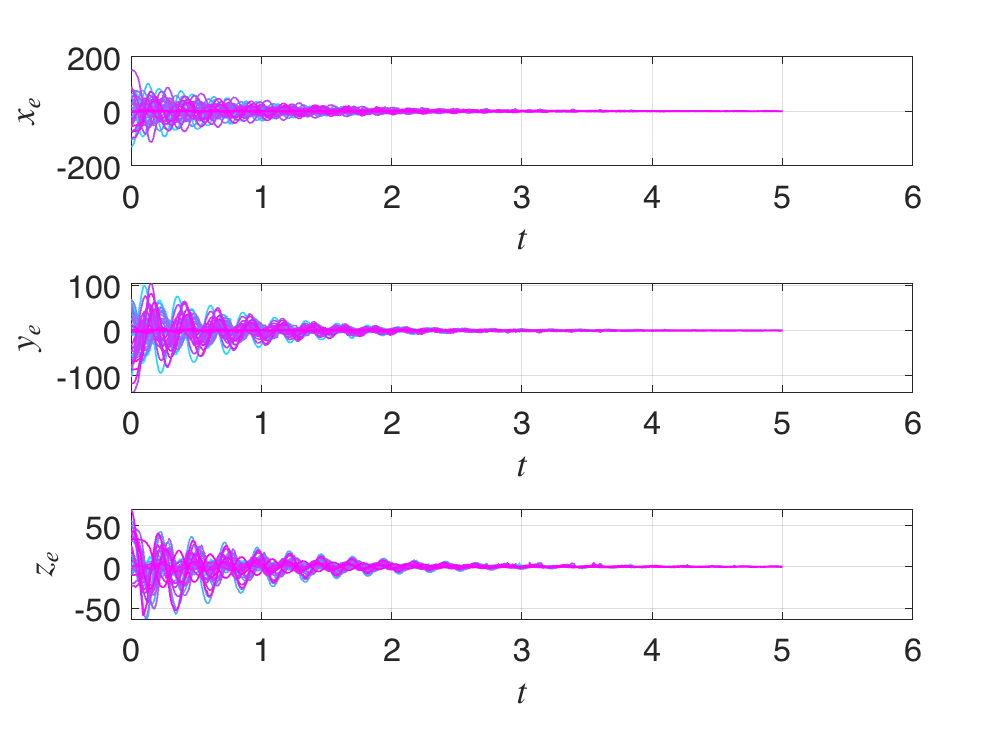

trajs = [13, 14, 15];
numTraj = length(trajs);
customFigure('subPlot',[numTraj 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numTraj
    subplot(numTraj,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numTraj
        subplot(numTraj,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

## PCA

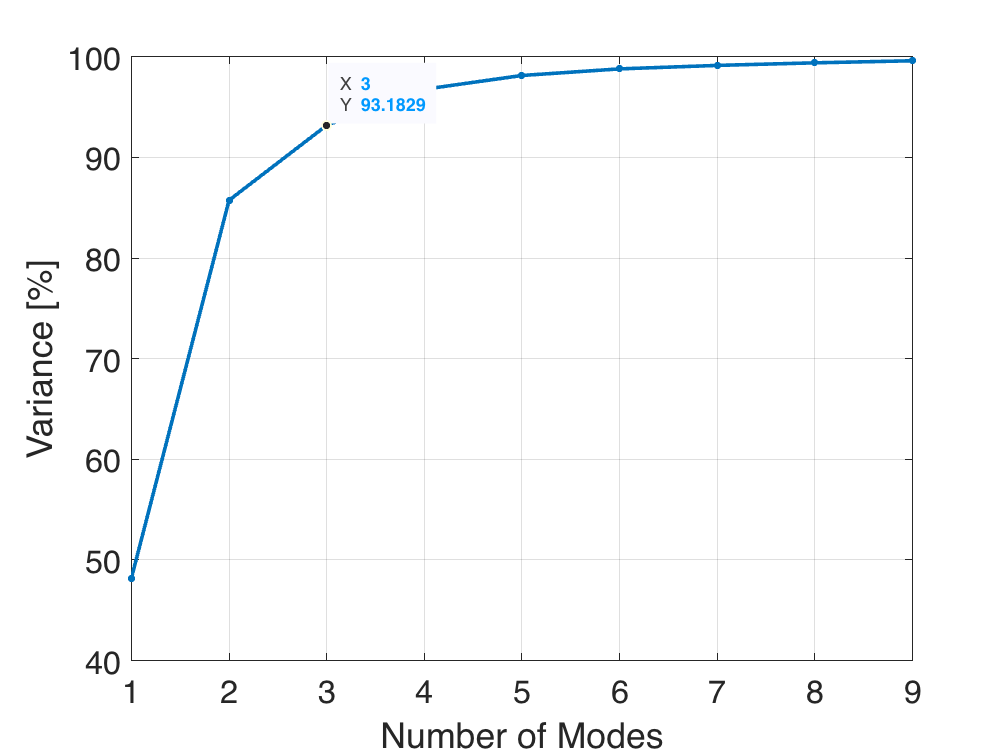

Xsnapshots = cat(2,oData{:,2});
% Perform SVD on displacement field
[~,S,~] = svd(Xsnapshots, 0);
% Plot variance description: we expect three modes to capture almost all
% variance. Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 9])
set(gca,'XTick',[1:1:9])